# Neural Networks

## What are neural networks?

**Neural networks** are a set of algorithms that were inspired by neural circuits in the brain, and have exploded in popularity due to advances in computing technology. These algorithms use information from the most informative features in the dataset to "learn" two parameters that can be used applied to other datasets.

Neural networks are powerful algorithms that can be applied to complex problems with dynamic features. We'll first use a synthetic dataset to demonstrate the concepts and mathematics underpinning a simple neural network. Then we'll work on building our own neural network and analyze the Framingham dataset. In the next lecture, we'll use neural networks to train a classifier on breast cancer imaging dataset to predict the degree of progression.

### The components and notation of a neural network

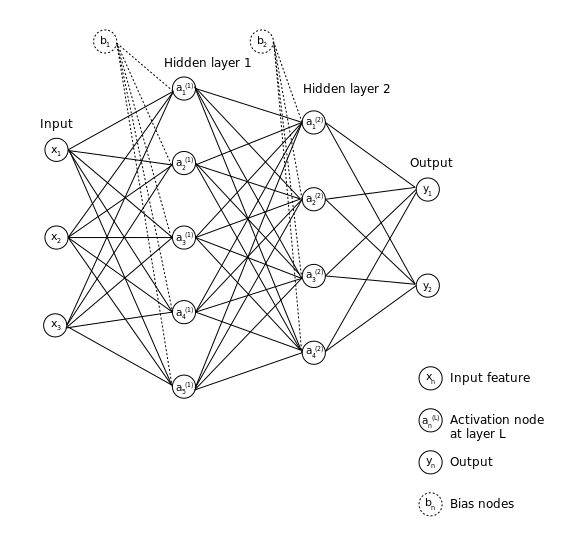

There are several flavors of neural network architectures, each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, a base model that contains the principles needed to understand how neural networks work generally. These principles can then be applied to construct other neural network variations. 

**Each component is described below:**

Input layer: the data ($X_{\textrm{train}}$) we are training the neural network on, where each $n^{\textrm{th}}$ column or feature vector represents a node in the network digram. The diagram above shows 3 features in the input layer.

Hidden layer(s): where the features are transformed into new data representations via linear and non-linear transformations

- Each **activation node** ($a_n$) represents our newly determined complex feature vector. A single hidden layer can consist of several activation nodes that may not necessarily correspond to the number of predictors we are inputting into the model. 

- The **bias nodes** ($b_n$) can be a scalar or vector of values that further influences the model fit. 

Output layer: the final computed values after processing the input data through the hidden layers. 

The diagram above shows a neural network containing two hidden layers - these are considered to be **deep neural networks **if there are multiple hidden layers. 

To illustrate the basic computations, however, we'll only be dealing with a **shallow neural network** that contains only 1 hidden layer, and three activation nodes. Thus, the network can be drawn as:

{Insert drawing}

## Training a neural network using forward propagation

The training phase of a neural network is called **forward propagation**, and consists of iteratively performing a linear transformation and non-linear transformation until we reach the output layer. 


$$X_{\mathrm{train}} \to^{\mathrm{Linear}} Z\to^{\mathrm{Nonlinear}} A\to^{\mathrm{Repeat}\;n\;\mathrm{times}} \;y_{\mathrm{pred}}$$


### Step 1: Linear transformation 

Let's consider our artificial dataset, which consists of 50 observations and 6 features. We'll start one activation node with the value of 1:

**The first step in training a neural network is to perform a linear transformation of the data**, similar to what you've seen in the linear regression part of the course, to compute a new "feature". The formulation for the 6 features is the following equation:


$$Z={1\cdot x}_1 +0{\cdot x}_2 +0{\cdot x}_3 +0{\cdot x}_4 +0{\cdot x}_5 +0{\cdot x}_6 +1$$
 

The vectorized form can be written as the following if the features span the rows of your data array:


$$Z=\;\mathrm{Xw}+b$$


The two parameters are the **weights** ($W$) and the **bias** ($b$) values, which is what the neural network algorithm is trying to optimize. 

Let's now plot the relationship between `Xtrain` `Z`:

% Plot Z with respect to input data
figure;
markersize = 10;
featureNames = ['1'; '2'; '3'; '4'; '5'; '6'];

hold on;
for i = 1:size(Xtrain, 2)
    scatter(Xtrain(:, i), Z_example1(:, i), ...
        markersize, ...
        'filled', ...
        'MarkerFaceAlpha', 0.8);
end

hold off;
lsline;
legend(featureNames, 'location', 'bestoutside');

xlabel('X_{train}');
ylabel('z');
title('Relationship between X_{train} and z');

As you can see, only one feature is linearly scaled, while the remaining features are randomly correlated with Z. 

Let's now add two other nodes to the network and see how they 

### Step 2: Non-linear transformation using the sigmoid function

**The second step involves transforming the data again using a non-linear function.** In this particular example, let's the sigmoid function. To review, data can be transformed to the characteristic 'S' curve using the following equation:


$$\mathrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


% Example sigmoid distribution
figure;
x = 0:0.1:10;
y = sigmf(x, [2, 4]);
plot(x, y);
hold on;
scatter(x, y, ...
    'filled', 'o',  ...
    'MarkerFaceAlpha', 0.6, ...
    'jitter', 'on', ...
    'jitterAmount', 0.5);
xlabel('Z');
ylabel('sigmoid(Z)');
ylim([-0.05, 1.05]);
title('Sigmoid function');

This function is useful for classification, especially if we're trying to predict two possible outcomes (a binary classification problem). This is due to the base `e` term in the denominator, which will either make the value `A` approach 0 if $z_i$ is large, or 1 if$z_i$ was small.

To implement the sigmoid function in MATLAB, we can use the `activationFnc` function provided in the project folder. Shown below are the relevant parts of the function used to transform the data using a sigmoidal function:

Let's see the results of our non-linear transformation on the second feature:

% Transform the new variable z using the sigmoid function
A = activationFnc(Z, 'Sigmoid');

% Plot a curve for Ypred with respect to input data
figure;
f = fit(Xtrain(:, 2), A, 'poly4');
plot(f, Xtrain(:, 2), A);
xlabel('X_{train}');
ylabel('y_{pred}');
title('Relationship between X_{train} and y_{pred}');
legend({'Feature 2'; 'Fit'}, 'location', 'southeast');

### Repeat until we reach the output layer

Let's finish the calculation and see the final output. The weights from the hidden layer to the output layer were a:

## Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through. We can do that using a cost function. Because we transformed the data using a sigmoid function, we can use the Cross-Entropy cost function.

#### **Cross-Entropy cost function**

For the case where we are using the sigmoid activation function, we can use the **Cross-Entropy (aka Log-Loss) cost function:**


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


$m$ = number of observations

$y_{\mathrm{train}}$ = the response variable

$y_{\textrm{pred}}$ = the predicted value for$y_{\mathrm{train}}$ from forward propagation

The **cost** value can be computed using the code from the `costFunction.mlx` script, which defines the cost function as follows:

## Optimizing neural network parameters using backward propagation

Finally, after computing the cost, we need to adjust the model parameters (`w` and `b)` until the error is below a given threshold or after a certain number of iterations. This can be done using an optimization algorithm we covered earlier in the course called gradient descent. To use gradient descent however, we need to **back propagate** and find the specific weights / biases that need to be changed to minimize the cost. 

### Optimizing parameters `W` and `b` using gradient descent

To review, the objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters, we have two equations to update:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\alpha \cdot \mathrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}-\left(\alpha \cdot \mathrm{db}\right)
\end{array}$$
 

$\alpha$ is the learning rate hyperparameter

### Finding dW and db using back propagation

To compute the gradient for `W` and `b` (`dW` and `db`), we need to see which weights and biases contribute the highest cost. We can set this up as two differential equations:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y_{\textrm{pred}} }\cdot \frac{\vartheta y_{\textrm{pred}} }{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

We won't go over the derivation of the terms, but the most relevant equations we need to update `W` and `b` are: 


$$\begin{array}{l}
{\mathrm{dZ}}^{\left\lbrack L\right\rbrack } =A^{\left\lbrack L\right\rbrack } -Y\\
d{\mathrm{W}}^{\left\lbrack L\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\mathrm{dZ}}^{\left\lbrack L\right\rbrack } \cdot A^{\left\lbrack L\right\rbrack \;T} \right)\\
{\mathrm{dZ}}^{\left\lbrack 1\right\rbrack } =W^{\left\lbrack 2\right\rbrack T} {\mathrm{dZ}}^{\left\lbrack 2\right\rbrack } {g^{\prime } }^{\left\lbrack 1\right\rbrack } \left(Z^1 \right)\\
d{\mathrm{W}}^{\left\lbrack 1\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\mathrm{dZ}}^{\left\lbrack 1\right\rbrack } \cdot A^{\left\lbrack 1\right\rbrack \;T} \right)\\
{\mathit{db}}^{\left\lbrack 1\right\rbrack } =\frac{1}{m}\sum_{i=1}^n \left({\mathrm{dZ}}^{\left\lbrack 1\right\rbrack } \right)
\end{array}$$
